# Create Differential Expression Containers

**Author**: Scott Campit

## Summary

This notebook creates data structures that contain differentially expressed genes from several bulk RNASeq and proteomics data studies. These data structures will be loaded into the `recon1_bulk_COBRA.mlx` and `ihuman_bulk_COBRA.mlx` files.

clear all;

## 1. GSE17708 Keshamouni RNASeq EMT data

GSE17708 contains the fold change and p-values from time-point transitions spanning $t_{0\textrm{hrs}}$ to $t_{72\textrm{hrs}}$ after $\textrm{TGF}\beta$ treatment. 

**The data can be found from this publication: **

Keshamouni, V. G., Jagtap, P., Michailidis, G., Strahler, J. R., Kuick, R., Reka, A. K., ... & Omenn, G. S. (2009). Temporal quantitative proteomics by iTRAQ 2D-LC-MS/MS and corresponding mRNA expression analysis identify post-transcriptional modulation of actin-cytoskeleton regulators during TGF-β-induced epithelial-mesenchymal transition. *Journal of proteome research*, *8*(1), 35-47. 

% LINUX
%filepath   = '~/Data/Expression/RNASeq/GSE17708/processed/GSE17708_processed.xlsx';

% DELL
filepath   = 'D:/Data/RNASeq/GSE17708/GSE17708_Keshamouni_TGFB1_logs.xls';

### A. Load data

% Get all data
foldchange = readcell(filepath, 'Sheet', 'FC');
pvalues    = readcell(filepath, 'Sheet', 'PValue');

### B. Get gene identifiers

geneids = string(foldchange(:, 1:5));

### C. Get data column names

fcids = string(foldchange(1, 6:13));

### D. Re-format data

foldchange = cell2mat(foldchange(2:end, 6:13));
pvalues = cell2mat(pvalues(2:end, 6:13));

### E. Visualize data

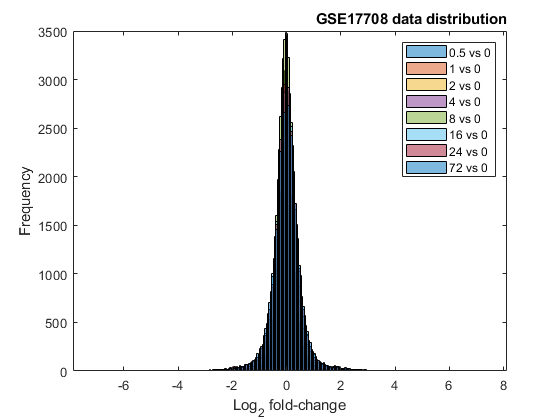

figure;
for i = 1:size(foldchange, 2)
    histogram(log2(foldchange(:, i)), 'FaceAlpha', 0.5);
    hold on;
end

% Label attributes
xlabel("Log_{2} fold-change");
ylabel("Frequency");

% Title attributes
t = title("GSE17708 data distribution");
set(t, 'horizontalAlignment', 'right');
set(t, 'units', 'normalized');
h1 = get(t, 'position');
set(t, 'position', [1, h1(2), h1(3)]);

% Legend
legend(fcids);

### F. Take log2 for the fold-change

foldchange = log2(foldchange);

### G. Create the data structure

% Save IDs
GSE17708.name = "GSE17708";
GSE17708.fcid = fcids;
GSE17708.geneids = geneids;

% Save raw data
GSE17708.fc = foldchange;
GSE17708.pvalue = pvalues;

% P-value < 0.05
data005 = foldchange;
data005(pvalues > 0.05) = NaN;
GSE17708.data005 = data005;

% P-value < 0.01
data001 = foldchange;
data001(pvalues > 0.01) = NaN;
GSE17708.data001 = data001;

### H. Save data

% DELL
savepath = "D:/Analysis/EMT/data/GSE17708.mat";
save(savepath, 'GSE17708');

## 2. GSE17518 Thannickal RNASeq EMT Data

GSE17518 contains two time points after $\textrm{TGF}\beta$ treatment. 

clear all;

**The data can be found from this publication:**

Hecker, L., Vittal, R., Jones, T., Jagirdar, R., Luckhardt, T. R., Horowitz, J. C., ... & Thannickal, V. J. (2009). NADPH oxidase-4 mediates myofibroblast activation and fibrogenic responses to lung injury. *Nature medicine*, *15*(9), 1077-1081.

% LINUX
%filepath       = '~/Data/Expression/RNASeq/GSE17518/GSE17518_processed.xlsx';

% DELL
filepath       = "D:/Data/RNASeq/GSE17518/GSE17518_DGE.xlsx";

### A. Load data

% Get all data
df             = readcell(filepath);

### B. Get gene identifiers

geneids = string(df(:, 1:3));

### C. Get data column names

fcids = string(df(1, 4:9));

### D. Re-format data

tscore  = cell2mat(df(2:end, 6));
pvalues = cell2mat(df(2:end, 8));

### E. Visualize data

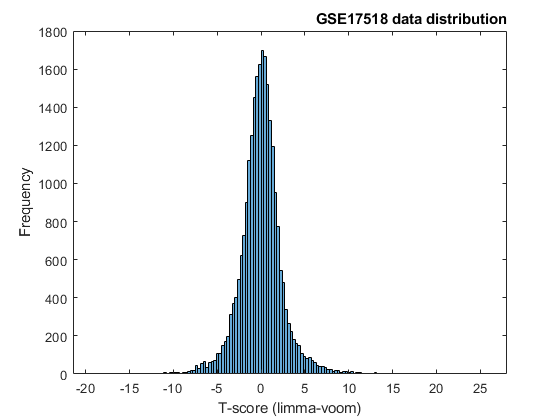

figure;
histogram(tscore);

% Label attributes
xlabel("T-score (limma-voom)");
ylabel("Frequency");

% Title attributes
t = title("GSE17518 data distribution");
set(t, 'horizontalAlignment', 'right');
set(t, 'units', 'normalized');
h1 = get(t, 'position');
set(t, 'position', [1, h1(2), h1(3)]);

### F. Create the data structure

% Save IDs
GSE17518.name    = "GSE17518";
GSE17518.fcid    = fcids;
GSE17518.geneids = geneids;
GSE17518.data    = cell2mat(df(2:end, 4:end));

% Save raw data
GSE17518.tscore = tscore;
GSE17518.pvalue = pvalues;

% P-value < 0.05
data005 = tscore;
data005(pvalues > 0.05) = NaN;
GSE17518.data005 = data005;

% P-value < 0.01
data001 = tscore;
data001(pvalues > 0.01) = NaN;
GSE17518.data001 = data001;

### G. Save data

% DELL
savepath = "D:/Analysis/EMT/data/GSE17518.mat";
save(savepath, 'GSE17518');

## 3. Garcia Proteomics

This proteomics dataset from Garcia and colleagues contains several time points from $t_{0\textrm{hrs}}$ to $t_{48\textrm{hrs}}$ after $\textrm{TGF}\beta$ treatment.

clear all;

**The data can be found from this publication:**

Lu, C., Sidoli, S., Kulej, K., Ross, K., Wu, C. H., & Garcia, B. A. (2019). Coordination between TGF-β cellular signaling and epigenetic regulation during epithelial to mesenchymal transition. *Epigenetics & chromatin*, *12*(1), 1-17.

% LINUX
%filepath       = '~/Data/Expression/RNASeq/GSE17518/GSE17518_processed.xlsx';

% DELL
filepath       = "D:/Data/Proteomics/Garcia/processed/garcia.xlsx";

### A. Load the data

df             = readcell(filepath);

### B. Get gene identifiers

geneids = string(df(:, 1:8));

### C. Get data column names

fcids = string(df(1, 9:end));

### D. Re-format data

% Format fold-changes
foldchange = str2double(string(df(2:end, 9:12)));
foldchange(isnan(foldchange)) = 0;

% Format P-values
pvalue = str2double(string(df(2:end, 13:16)));
pvalue = 2.^-pvalue;
pvalue(isnan(pvalue)) = 1;

pvalue =     0.6452    0.4727    0.4844    0.4517
    0.0338    0.0326    0.1709    0.0780
    1.0000    0.1838    0.4226    0.4226
    0.4226    0.4226    0.4226    0.4226
    0.0337    0.7854    0.3282    0.5500
    0.1207    0.4139    0.6696    0.7985
    0.3028    0.2760    0.1210    0.1078
    1.0000    0.0112    0.4226    0.4016
    0.1899    1.0000    1.0000    1.0000
    0.1480    0.5219    0.1755    0.0266


### E. Visualize data

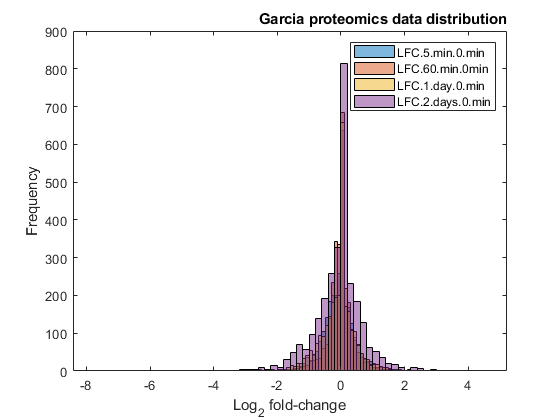

figure;
for i = 1:size(foldchange, 2)
    histogram(foldchange(:, i), 'FaceAlpha', 0.5);
    hold on;
end

% Label attributes
xlabel("Log_{2} fold-change");
ylabel("Frequency");

% Title attributes
t = title("Garcia proteomics data distribution");
set(t, 'horizontalAlignment', 'right');
set(t, 'units', 'normalized');
h1 = get(t, 'position');
set(t, 'position', [1, h1(2), h1(3)]);

% Legend
legend(fcids(1:4));

### F. Create the data structure

% Save IDs
Garcia.name    = "Garcia EMT proteomics data";
Garcia.fcid    = fcids;
Garcia.geneids = geneids;

% Save raw data
Garcia.fc      = foldchange;
Garcia.pvalue  = pvalue;

% P-value < 0.05
data005 = foldchange;
data005(pvalue > 0.05) = NaN;
Garcia.data005 = data005;

% P-value < 0.01
data001 = foldchange;
data001(pvalue > 0.01) = NaN;
Garcia.data001 = data001;

### H. Save data

% DELL
savepath = "D:/Analysis/EMT/data/Garcia.mat";
save(savepath, 'Garcia');

## Conclusions

This creates 3 data files that store the data. This can be fed into COBRA.